% пробую сгенерить си код

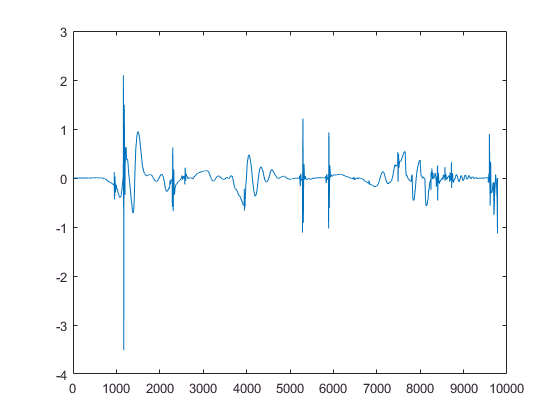

x=tYawAcc(:, 2);
plot(x)

nWht = 64

nWht = 64

n_section = 6

n_section = 6

nSectionPlus=7;
msp = zeros(1, 64);
load("kwhd.mat")
load("dSigm.mat")
kw = kwh64(:,4:51);
ik0=1:2:length(mWhCalc);

Undefined function or variable 'mWhCalc'.

ik1=1:2:length(mWhCalc);


nnn = 1201;
y00 = 1:1201;
y01 =1.3* sin(6*2*pi/64*y00);
plot(y01)
x=y01;


yy00 = y01(1:64);
y = abs(fwht(yy00));
%plot(y)
mWhCalc=abs(yy00*kw);
ik0=1:2:length(mWhCalc);
ik1=1:2:length(mWhCalc);
m0=mWhCalc(ik0) + mWhCalc(ik1);
energy = sum(m0)
figure
bar(m0)

wh_deg = WhDebagSimul();
%x=tYawAcc(:, 2);
plot(x)
plot(x(1:nnn))
msp(:)=0;
v0=zeros(nnn, 24);
v1=zeros(nnn, 1);

%for ix=1:nnn    %length(x)
for ix=1: length(x)
    msp(1, 2:nWht) = msp(1, 1:nWht-1);
    msp(1,1) = x(ix);
    v1(ix, 1)=sum(abs(msp*kw));
    
end
plot(v1)
disp(" расчет закончен ")


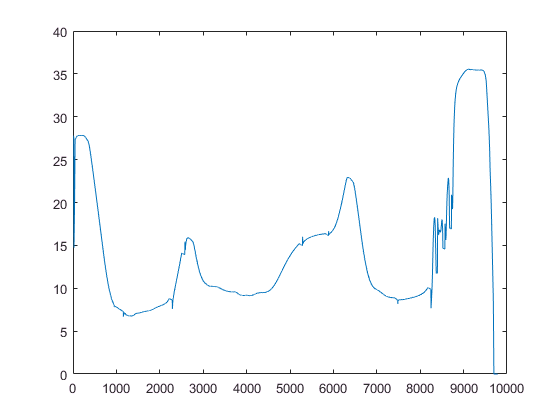

vBelt=tvBelt(:, 2);
plot(vBelt)

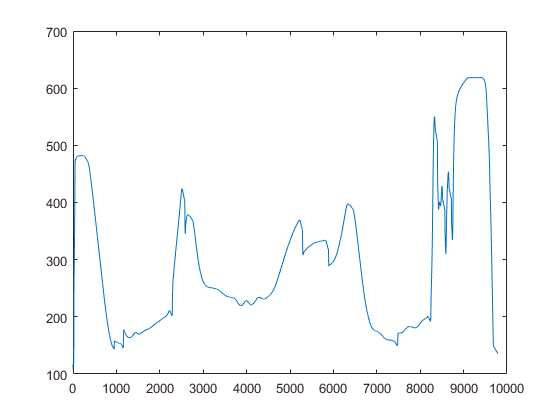

rotv=trotv(:, 2);
plot(rotv)

dSlipp = zeros(1, 50);
lSlipp = length(dSlipp)

lSlipp = 50


Rwheel=17*0.0254

Rwheel = 0.4318

Transfer = 3

Transfer = 3

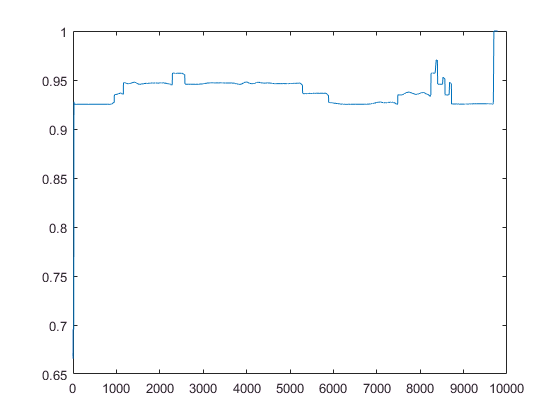

R =  Rwheel * Transfer;
            
slipp = 1 - (vBelt./rotv*R );            
plot(slipp)

ind =1 

ind = 1

dSlipp(:)=0.0;
%vK = zeros(1,300);
vK = zeros(1, length(slipp));
for i=1: length(slipp)
    dSlipp( 2:lSlipp) = dSlipp(1:lSlipp-1);
    dSlipp(1) = slipp(i);
    i% I - Режим формирования массива dSlipp     
    if dSlipp(lSlipp)==0
        continue;
    end
    
    sr = sum(dSlipp)/length(dSlipp);
    sd = std(dSlipp);
    
% II - Режим ind == 1
    if ind==1
        if dSlipp(1)>(sr + sd)   
            ind=min(ind+1, 6);
            continue;
        end            
        if dSlipp(1)<(sr - sd)   
            ind=max(ind-1, 1);
            continue;
        end
        continue;
    end
    
% III - Режим ind > 1
    if (dSlipp(1)>(sr + sd)) & (dSlipp(1)>dSlipp(2))
        ind=min(ind+1, 6);
        continue;
    end
    if (dSlipp(1)<(sr - sd)) & (dSlipp(1)<dSlipp(2))
        ind=max(ind-1, 1);
        continue;
    end
    dSlipp(1)=dSlipp(2);        
        
    vK(i) = ind;    
end

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24

i = 25

i = 26

i = 27

i = 28

i = 29

i = 30

i = 31

i = 32

i = 33

i = 34

i = 35

i = 36

i = 37

i = 38

i = 39

i = 40

i = 41

i = 42

i = 43

i = 44

i = 45

i = 46

i = 47

i = 48

i = 49

i = 50

i = 51

i = 52

i = 53

i = 54

i = 55

i = 56

i = 57

i = 58

i = 59

i = 60

i = 61

i = 62

i = 63

i = 64

i = 65

i = 66

i = 67

i = 68

i = 69

i = 70

i = 71

i = 72

i = 73

i = 74

i = 75

i = 76

i = 77

i = 78

i = 79

i = 80

i = 81

i = 82

i = 83

i = 84

i = 85

i = 86

i = 87

i = 88

i = 89

i = 90

i = 91

i = 92

i = 93

i = 94

i = 95

i = 96

i = 97

i = 98

i = 99

i = 100

i = 101

i = 102

i = 103

i = 104

i = 105

ind = 2

i = 106

ind = 3

i = 107

ind = 4

i = 108

ind = 5

i = 109

ind = 6

i = 110

ind = 6

i = 111

ind = 6

i = 112

ind = 6

i = 113

ind = 6

i = 114

ind = 6

i = 115

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 116

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 117

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 118

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 119

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 120

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 121

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 122

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 123

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 124

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 125

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 126

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 127

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 128

ind = 6

i = 129

ind = 6

i = 130

ind = 6

i = 131

ind = 6

i = 132

ind = 6

i = 133

ind = 6

i = 134

ind = 6

i = 135

ind = 6

i = 136

ind = 6

i = 137

ind = 6

i = 138

ind = 6

i = 139

ind = 6

i = 140

ind = 6

i = 141

ind = 6

i = 142

ind = 6

i = 143

ind = 6

i = 144

ind = 6

i = 145

ind = 6

i = 146

ind = 6

i = 147

ind = 6

i = 148

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 149

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 150

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 151

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 152

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 153

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 154

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 155

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 156

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 157

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 158

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 159

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 160

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 161

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 162

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 163

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 164

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 165

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 166

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 167

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 168

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 169

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 170

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 171

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 172

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 173

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 174

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 175

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 176

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 177

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 178

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 179

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 180

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 181

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 182

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 183

ind = 6

i = 184

ind = 6

i = 185

ind = 6

i = 186

ind = 6

i = 187

ind = 6

i = 188

ind = 6

i = 189

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 190

ind = 6

i = 191

ind = 6

i = 192

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 193

ind = 6

i = 194

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 195

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 196

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 197

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 198

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 199

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 200

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 201

ind = 6

i = 202

ind = 6

i = 203

ind = 6

i = 204

ind = 6

i = 205

ind = 6

i = 206

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 207

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 208

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 209

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 210

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 211

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 212

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 213

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 214

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 215

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 216

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 217

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 218

ind = 5

i = 219

ind = 4

i = 220

ind = 3

i = 221

ind = 2

i = 222

ind = 1

i = 223

ind = 1

i = 224

ind = 1

i = 225

ind = 1

i = 226

ind = 1

i = 227

ind = 1

i = 228

ind = 1

i = 229

ind = 1

i = 230

ind = 1

i = 231

ind = 1

i = 232

ind = 1

i = 233

ind = 1

i = 234

ind = 1

i = 235

ind = 1

i = 236

ind = 1

i = 237

ind = 1

i = 238

ind = 1

i = 239

ind = 1

i = 240

ind = 1

i = 241

ind = 1

i = 242

ind = 1

i = 243

ind = 1

i = 244

ind = 1

i = 245

ind = 1

i = 246

i = 247

i = 248

i = 249

i = 250

i = 251

i = 252

i = 253

i = 254

i = 255

i = 256

i = 257

i = 258

i = 259

i = 260

i = 261

i = 262

i = 263

i = 264

i = 265

i = 266

i = 267

i = 268

i = 269

i = 270

i = 271

i = 272

i = 273

i = 274

i = 275

ind = 2

i = 276

ind = 3

i = 277

ind = 4

i = 278

ind = 5

i = 279

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 280

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 281

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 282

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 283

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 284

ind = 4

i = 285

ind = 3

i = 286

ind = 2

i = 287

ind = 1

i = 288

ind = 1

i = 289

ind = 1

i = 290

ind = 1

i = 291

ind = 1

i = 292

ind = 1

i = 293

ind = 1

i = 294

ind = 1

i = 295

ind = 1

i = 296

ind = 1

i = 297

ind = 1

i = 298

ind = 1

i = 299

ind = 1

i = 300

ind = 1

i = 301

i = 302

i = 303

i = 304

i = 305

i = 306

i = 307

i = 308

i = 309

i = 310

i = 311

ind = 2

i = 312

ind = 3

i = 313

ind = 4

i = 314

ind = 5

i = 315

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 316

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 317

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 318

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 319

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 320

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 321

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 322

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 323

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 324

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 325

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 326

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 327

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 328

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 329

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 330

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 331

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 332

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 333

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 334

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 335

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 336

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 337

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 338

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 339

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 340

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 341

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 342

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 343

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 344

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 345

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 346

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 347

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 348

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 349

ind = 6

i = 350

ind = 6

i = 351

ind = 6

i = 352

ind = 6

i = 353

ind = 6

i = 354

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 355

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 356

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 357

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 358

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 359

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 360

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 361

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 362

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 363

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 364

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 365

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 366

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 367

ind = 5

i = 368

ind = 4

i = 369

ind = 3

i = 370

ind = 2

i = 371

ind = 1

i = 372

ind = 1

i = 373

ind = 1

i = 374

ind = 1

i = 375

ind = 1

i = 376

ind = 1

i = 377

ind = 1

i = 378

ind = 1

i = 379

ind = 1

i = 380

ind = 1

i = 381

ind = 1

i = 382

ind = 1

i = 383

ind = 1

i = 384

ind = 1

i = 385

ind = 1

i = 386

ind = 1

i = 387

ind = 1

i = 388

ind = 1

i = 389

ind = 1

i = 390

ind = 1

i = 391

ind = 1

i = 392

ind = 1

i = 393

ind = 1

i = 394

ind = 1

i = 395

ind = 1

i = 396

ind = 1

i = 397

ind = 1

i = 398

ind = 1

i = 399

ind = 1

i = 400

ind = 1

i = 401

ind = 1

i = 402

ind = 1

i = 403

ind = 1

i = 404

ind = 1

i = 405

ind = 1

i = 406

ind = 1

i = 407

ind = 1

i = 408

ind = 1

i = 409

ind = 1

i = 410

ind = 1

i = 411

ind = 1

i = 412

ind = 1

i = 413

ind = 1

i = 414

ind = 1

i = 415

ind = 1

i = 416

ind = 1

i = 417

ind = 1

i = 418

ind = 1

i = 419

ind = 1

i = 420

ind = 1

i = 421

ind = 1

i = 422

ind = 1

i = 423

ind = 1

i = 424

ind = 1

i = 425

ind = 1

i = 426

ind = 1

i = 427

ind = 1

i = 428

ind = 1

i = 429

ind = 1

i = 430

ind = 1

i = 431

ind = 1

i = 432

ind = 1

i = 433

ind = 1

i = 434

ind = 1

i = 435

ind = 1

i = 436

ind = 1

i = 437

ind = 1

i = 438

ind = 1

i = 439

ind = 1

i = 440

ind = 1

i = 441

ind = 1

i = 442

ind = 1

i = 443

ind = 1

i = 444

ind = 1

i = 445

ind = 1

i = 446

ind = 1

i = 447

ind = 1

i = 448

ind = 1

i = 449

ind = 1

i = 450

ind = 1

i = 451

ind = 1

i = 452

ind = 1

i = 453

ind = 1

i = 454

ind = 1

i = 455

ind = 1

i = 456

i = 457

i = 458

i = 459

i = 460

i = 461

i = 462

i = 463

i = 464

i = 465

i = 466

i = 467

i = 468

i = 469

i = 470

i = 471

i = 472

i = 473

i = 474

i = 475

i = 476

i = 477

i = 478

i = 479

i = 480

i = 481

i = 482

ind = 2

i = 483

ind = 3

i = 484

ind = 4

i = 485

ind = 5

i = 486

ind = 6

i = 487

ind = 6

i = 488

ind = 6

i = 489

ind = 6

i = 490

ind = 6

i = 491

ind = 6

i = 492

ind = 6

i = 493

ind = 6

i = 494

ind = 6

i = 495

ind = 6

i = 496

ind = 6

i = 497

ind = 6

i = 498

ind = 6

i = 499

ind = 6

i = 500

ind = 6

i = 501

ind = 6

i = 502

ind = 6

i = 503

ind = 6

i = 504

ind = 6

i = 505

ind = 6

i = 506

ind = 6

i = 507

ind = 6

i = 508

ind = 6

i = 509

ind = 6

i = 510

ind = 6

i = 511

ind = 6

i = 512

ind = 6

i = 513

ind = 6

i = 514

ind = 6

i = 515

ind = 6

i = 516

ind = 6

i = 517

ind = 6

i = 518

ind = 6

i = 519

ind = 6

i = 520

ind = 6

i = 521

ind = 6

i = 522

ind = 6

i = 523

ind = 6

i = 524

ind = 6

i = 525

ind = 6

i = 526

ind = 6

i = 527

ind = 6

i = 528

ind = 6

i = 529

ind = 6

i = 530

ind = 6

i = 531

ind = 6

i = 532

ind = 6

i = 533

ind = 6

i = 534

ind = 6

i = 535

ind = 6

i = 536

ind = 6

i = 537

ind = 6

i = 538

ind = 6

i = 539

ind = 6

i = 540

ind = 6

i = 541

ind = 6

i = 542

ind = 6

i = 543

ind = 6

i = 544

ind = 6

i = 545

ind = 6

i = 546

ind = 6

i = 547

ind = 6

i = 548

ind = 6

i = 549

ind = 6

i = 550

ind = 6

i = 551

ind = 6

i = 552

ind = 6

i = 553

ind = 6

i = 554

ind = 6

i = 555

ind = 6

i = 556

ind = 6

i = 557

ind = 6

i = 558

ind = 6

i = 559

ind = 6

i = 560

ind = 6

i = 561

ind = 6

i = 562

ind = 6

i = 563

ind = 6

i = 564

ind = 6

i = 565

ind = 6

i = 566

ind = 6

i = 567

ind = 6

i = 568

ind = 6

i = 569

ind = 6

i = 570

ind = 6

i = 571

ind = 6

i = 572

ind = 6

i = 573

ind = 6

i = 574

ind = 6

i = 575

ind = 6

i = 576

ind = 6

i = 577

ind = 6

i = 578

ind = 6

i = 579

ind = 6

i = 580

ind = 6

i = 581

ind = 6

i = 582

ind = 6

i = 583

ind = 6

i = 584

ind = 6

i = 585

ind = 6

i = 586

ind = 6

i = 587

ind = 6

i = 588

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 589

ind = 6

i = 590

ind = 6

i = 591

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 592

ind = 6

i = 593

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 594

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 595

ind = 6

i = 596

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 597

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 598

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 599

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 600

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 601

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 602

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 603

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 604

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 605

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 606

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 607

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 608

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 609

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 610

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 611

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 612

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 613

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 614

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 615

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 616

ind = 5

i = 617

ind = 4

i = 618

ind = 3

i = 619

ind = 2

i = 620

ind = 1

i = 621

ind = 1

i = 622

ind = 1

i = 623

ind = 1

i = 624

ind = 1

i = 625

ind = 1

i = 626

ind = 1

i = 627

ind = 1

i = 628

ind = 1

i = 629

ind = 1

i = 630

ind = 1

i = 631

ind = 1

i = 632

ind = 1

i = 633

ind = 1

i = 634

ind = 1

i = 635

ind = 1

i = 636

ind = 1

i = 637

ind = 1

i = 638

ind = 1

i = 639

ind = 1

i = 640

ind = 1

i = 641

ind = 1

i = 642

ind = 1

i = 643

ind = 1

i = 644

ind = 1

i = 645

ind = 1

i = 646

ind = 1

i = 647

ind = 1

i = 648

ind = 1

i = 649

ind = 1

i = 650

ind = 1

i = 651

ind = 1

i = 652

ind = 1

i = 653

ind = 1

i = 654

ind = 1

i = 655

ind = 1

i = 656

ind = 1

i = 657

ind = 1

i = 658

ind = 1

i = 659

ind = 1

i = 660

ind = 1

i = 661

ind = 1

i = 662

ind = 1

i = 663

ind = 1

i = 664

ind = 1

i = 665

ind = 1

i = 666

ind = 1

i = 667

ind = 1

i = 668

ind = 1

i = 669

ind = 1

i = 670

ind = 1

i = 671

ind = 1

i = 672

ind = 1

i = 673

ind = 1

i = 674

ind = 1

i = 675

ind = 1

i = 676

ind = 1

i = 677

ind = 1

i = 678

ind = 1

i = 679

ind = 1

i = 680

ind = 1

i = 681

ind = 1

i = 682

ind = 1

i = 683

ind = 1

i = 684

ind = 1

i = 685

ind = 1

i = 686

ind = 1

i = 687

ind = 1

i = 688

ind = 1

i = 689

ind = 1

i = 690

ind = 1

i = 691

ind = 1

i = 692

ind = 1

i = 693

ind = 1

i = 694

ind = 1

i = 695

ind = 1

i = 696

ind = 1

i = 697

ind = 1

i = 698

ind = 1

i = 699

ind = 1

i = 700

ind = 1

i = 701

ind = 1

i = 702

ind = 1

i = 703

ind = 1

i = 704

ind = 1

i = 705

ind = 1

i = 706

ind = 1

i = 707

ind = 1

i = 708

ind = 1

i = 709

ind = 1

i = 710

ind = 1

i = 711

ind = 1

i = 712

ind = 1

i = 713

ind = 1

i = 714

ind = 1

i = 715

ind = 1

i = 716

ind = 1

i = 717

ind = 1

i = 718

ind = 1

i = 719

ind = 1

i = 720

ind = 1

i = 721

ind = 1

i = 722

ind = 1

i = 723

ind = 1

i = 724

ind = 1

i = 725

ind = 1

i = 726

ind = 1

i = 727

ind = 1

i = 728

ind = 1

i = 729

ind = 1

i = 730

ind = 1

i = 731

ind = 1

i = 732

ind = 1

i = 733

ind = 1

i = 734

ind = 1

i = 735

ind = 1

i = 736

ind = 1

i = 737

ind = 1

i = 738

i = 739

i = 740

i = 741

i = 742

i = 743

i = 744

i = 745

i = 746

i = 747

i = 748

i = 749

i = 750

i = 751

ind = 2

i = 752

ind = 3

i = 753

ind = 4

i = 754

ind = 5

i = 755

ind = 6

i = 756

ind = 6

i = 757

ind = 6

i = 758

ind = 6

i = 759

ind = 6

i = 760

ind = 6

i = 761

ind = 6

i = 762

ind = 6

i = 763

ind = 6

i = 764

ind = 6

i = 765

ind = 6

i = 766

ind = 6

i = 767

ind = 6

i = 768

ind = 6

i = 769

ind = 6

i = 770

ind = 6

i = 771

ind = 6

i = 772

ind = 6

i = 773

ind = 6

i = 774

ind = 6

i = 775

ind = 6

i = 776

ind = 6

i = 777

ind = 6

i = 778

ind = 6

i = 779

ind = 6

i = 780

ind = 6

i = 781

ind = 6

i = 782

ind = 6

i = 783

ind = 6

i = 784

ind = 6

i = 785

ind = 6

i = 786

ind = 6

i = 787

ind = 6

i = 788

ind = 6

i = 789

ind = 6

i = 790

ind = 6

i = 791

ind = 6

i = 792

ind = 6

i = 793

ind = 6

i = 794

ind = 6

i = 795

ind = 6

i = 796

ind = 6

i = 797

ind = 6

i = 798

ind = 6

i = 799

ind = 6

i = 800

ind = 6

i = 801

ind = 6

i = 802

ind = 6

i = 803

ind = 6

i = 804

ind = 6

i = 805

ind = 6

i = 806

ind = 6

i = 807

ind = 6

i = 808

ind = 6

i = 809

ind = 6

i = 810

ind = 6

i = 811

ind = 6

i = 812

ind = 6

i = 813

ind = 6

i = 814

ind = 6

i = 815

ind = 6

i = 816

ind = 6

i = 817

ind = 6

i = 818

ind = 6

i = 819

ind = 6

i = 820

ind = 6

i = 821

ind = 6

i = 822

ind = 6

i = 823

ind = 6

i = 824

ind = 6

i = 825

ind = 6

i = 826

ind = 6

i = 827

ind = 6

i = 828

ind = 6

i = 829

ind = 6

i = 830

ind = 6

i = 831

ind = 6

i = 832

ind = 6

i = 833

ind = 6

i = 834

ind = 6

i = 835

ind = 6

i = 836

ind = 6

i = 837

ind = 6

i = 838

ind = 6

i = 839

ind = 6

i = 840

ind = 6

i = 841

ind = 6

i = 842

ind = 6

i = 843

ind = 6

i = 844

ind = 6

i = 845

ind = 6

i = 846

ind = 6

i = 847

ind = 6

i = 848

ind = 6

i = 849

ind = 6

i = 850

ind = 6

i = 851

ind = 6

i = 852

ind = 6

i = 853

ind = 6

i = 854

ind = 6

i = 855

ind = 6

i = 856

ind = 6

i = 857

ind = 6

i = 858

ind = 6

i = 859

ind = 6

i = 860

ind = 6

i = 861

ind = 6

i = 862

ind = 6

i = 863

ind = 6

i = 864

ind = 6

i = 865

ind = 6

i = 866

ind = 6

i = 867

ind = 6

i = 868

ind = 6

i = 869

ind = 6

i = 870

ind = 6

i = 871

ind = 6

i = 872

ind = 6

i = 873

ind = 6

i = 874

ind = 6

i = 875

ind = 6

i = 876

ind = 6

i = 877

ind = 6

i = 878

ind = 6

i = 879

ind = 6

i = 880

ind = 6

i = 881

ind = 6

i = 882

ind = 6

i = 883

ind = 6

i = 884

ind = 6

i = 885

ind = 6

i = 886

ind = 6

i = 887

ind = 6

i = 888

ind = 6

i = 889

ind = 6

i = 890

ind = 6

i = 891

ind = 6

i = 892

ind = 6

i = 893

ind = 6

i = 894

ind = 6

i = 895

ind = 6

i = 896

ind = 6

i = 897

ind = 6

i = 898

ind = 6

i = 899

ind = 6

i = 900

ind = 6

i = 901

ind = 6

i = 902

ind = 6

i = 903

ind = 6

i = 904

ind = 6

i = 905

ind = 6

i = 906

ind = 6

i = 907

ind = 6

i = 908

ind = 6

i = 909

ind = 6

i = 910

ind = 6

i = 911

ind = 6

i = 912

ind = 6

i = 913

ind = 6

i = 914

ind = 6

i = 915

ind = 6

i = 916

ind = 6

i = 917

ind = 6

i = 918

ind = 6

i = 919

ind = 6

i = 920

ind = 6

i = 921

ind = 6

i = 922

ind = 6

i = 923

ind = 6

i = 924

ind = 6

i = 925

ind = 6

i = 926

ind = 6

i = 927

ind = 6

i = 928

ind = 6

i = 929

ind = 6

i = 930

ind = 6

i = 931

ind = 6

i = 932

ind = 6

i = 933

ind = 6

i = 934

ind = 6

i = 935

ind = 6

i = 936

ind = 6

i = 937

ind = 6

i = 938

ind = 6

i = 939

ind = 6

i = 940

ind = 6

i = 941

ind = 6

i = 942

ind = 6

i = 943

ind = 6

i = 944

ind = 6

i = 945

ind = 6

i = 946

ind = 6

i = 947

ind = 6

i = 948

ind = 6

i = 949

ind = 6

i = 950

ind = 6

i = 951

ind = 6

i = 952

ind = 6

i = 953

ind = 6

i = 954

ind = 6

i = 955

ind = 6

i = 956

ind = 6

i = 957

ind = 6

i = 958

ind = 6

i = 959

ind = 6

i = 960

ind = 6

i = 961

ind = 6

i = 962

ind = 6

i = 963

ind = 6

i = 964

ind = 6

i = 965

ind = 6

i = 966

ind = 6

i = 967

ind = 6

i = 968

ind = 6

i = 969

ind = 6

i = 970

ind = 6

i = 971

ind = 6

i = 972

ind = 6

i = 973

ind = 6

i = 974

ind = 6

i = 975

ind = 6

i = 976

ind = 6

i = 977

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 978

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 979

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 980

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 981

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 982

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 983

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 984

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 985

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 986

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 987

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 988

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 989

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 990

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 991

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 992

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 993

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 994

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 995

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 996

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 997

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 998

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 999

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 1000

vK =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


i = 1001

ind = 6

i = 1002

ind = 6

i = 1003

ind = 6

i = 1004

ind = 6

i = 1005

ind = 6

i = 1006

ind = 6

i = 1007

ind = 6

i = 1008

ind = 6

i = 1009

ind = 6

i = 1010

ind = 6

i = 1011

ind = 6

i = 1012

ind = 6

i = 1013

ind = 6

i = 1014

ind = 6

i = 1015

ind = 6

i = 1016

ind = 6

i = 1017

ind = 6

i = 1018

ind = 6

i = 1019

ind = 6

i = 1020

ind = 6

i = 1021

ind = 6

i = 1022

ind = 6

i = 1023

ind = 6

i = 1024

ind = 6

i = 1025

ind = 6

i = 1026

ind = 6

i = 1027

ind = 6

i = 1028

ind = 6

i = 1029

ind = 6

i = 1030

ind = 6

i = 1031

ind = 6

i = 1032

ind = 6

i = 1033

ind = 6

i = 1034

ind = 6

i = 1035

ind = 6

i = 1036

ind = 6

i = 1037

ind = 6

i = 1038

ind = 6

i = 1039

ind = 6

i = 1040

ind = 6

i = 1041

ind = 6

i = 1042

ind = 6

i = 1043

ind = 6

i = 1044

ind = 6

i = 1045

ind = 6

i = 1046

ind = 6

i = 1047

ind = 6

i = 1048

ind = 6

i = 1049

ind = 6

i = 1050

ind = 6

i = 1051

ind = 6

i = 1052

ind = 6

i = 1053

ind = 6

i = 1054

ind = 6

i = 1055

ind = 6

i = 1056

ind = 6

i = 1057

ind = 6

i = 1058

ind = 6

i = 1059

ind = 6

i = 1060

ind = 6

i = 1061

ind = 6

i = 1062

ind = 6

i = 1063

ind = 6

i = 1064

ind = 6

i = 1065

ind = 6

i = 1066

ind = 6

i = 1067

ind = 6

i = 1068

ind = 6

i = 1069

ind = 6

i = 1070

ind = 6

i = 1071

ind = 6

i = 1072

ind = 6

i = 1073

ind = 6

i = 1074

ind = 6

i = 1075

ind = 6

i = 1076

ind = 6

i = 1077

ind = 6

i = 1078

ind = 6

i = 1079

ind = 6

i = 1080

ind = 6

i = 1081

ind = 6

i = 1082

ind = 6

i = 1083

ind = 6

i = 1084

ind = 6

i = 1085

ind = 6

i = 1086

plot(vK)

